#### Skupne konstante

N=2000;
t=linspace(0,N-1,N);    % časovni vektor

#### Pravokotna signala

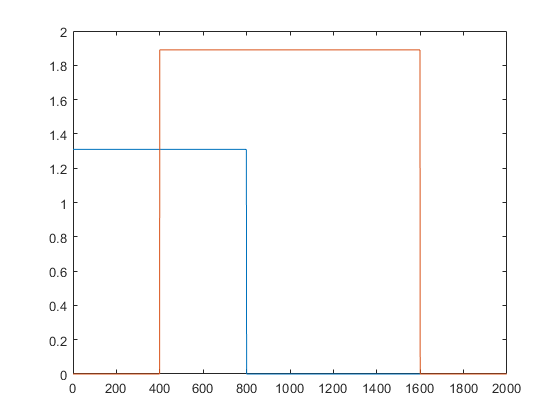

dpa=800;        % dolžina signala Xpa
dpb=1200;       % dolžina signala Xpb
x0pa=0;         % začetek signala Xpa
x0pb=400;       % začetek signala Xpb
Apa=1.31;       % amplituda signala Xpa
Apb=1.89;       % amplituda signala Xpb

xpa=zeros(1,N);
xpb=zeros(1,N);
xpa((t>=x0pa) & (t<(x0pa+dpa)))=Apa;
xpb(t>=x0pb & t<(x0pb+dpb))=Apb;

plot(t,xpa,t,xpb)      % izris

#### Trikotni signal

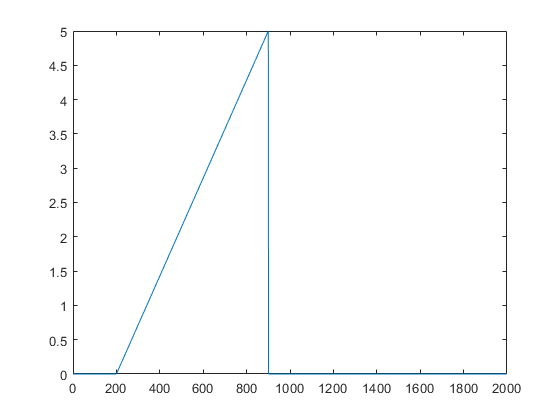


dt=700;         % dolžina signala Xpa
x0t=200;        % začetek signala Xpa
At=5;           % amplituda signala Xpa
kt=At/dt;       % izračun strmine
y0t=-x0t*kt;    % izračun presečišča z y osjo
xt=kt.*t+y0t;   
xt(t<x0t)=0;
xt(t>(x0t+dt))=0;

plot(t,xt)      % izris

#### Sinusna signala

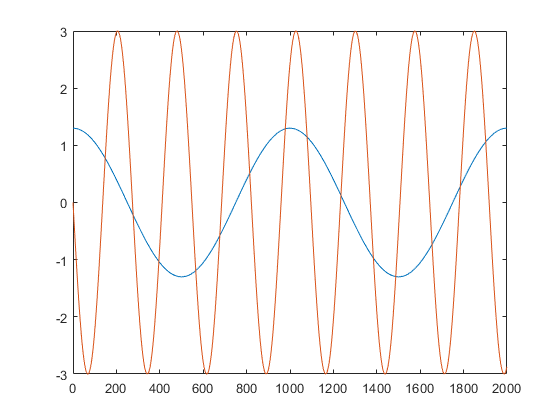

Asa=1.3;        % amplituda signala Xsa
Asb=3;          % amplituda signala Xsb
npsa=2;         % število period Xsa
npsb=7.3;       % število period Xsb
freksa=npsa/N;  % frekvenca Xsa
freksb=npsb/N;  % frekvenca Xsb
fazasa=pi/2;    % faza Xsa
fazasb=-pi;     % faza Xsb
xsa=Asa*sin(2*pi*freksa*t+fazasa);
xsb=Asb*sin(2*pi*freksb*t+fazasb);

plot(t,xsa,t,xsb)      % izris